## Setting up model

clear

init_basketball_shooting;
mdl = 'model_basketball_shooting';
open_system(mdl)

phi_vec = 45:1:65;
v0_vec  = zeros(size(phi_vec));

## Find best initial speed

try many values and find the makes

makes_list = cell(size(phi_vec));
N = length(phi_vec);
v0_trial = 6.50:0.01:8.00;
NN = length(v0_trial);

for i = 1:N
    
    for ii = 1:NN
        in(ii) = Simulink.SimulationInput(mdl);
        in(ii) = in(ii).setVariable('phi',   phi_vec(i)); 
        in(ii) = in(ii).setVariable('v0' , v0_trial(ii)); 
    end

    % Simulate the model
    out = sim(in);  % simulation in series
    % out = parsim(in,'TransferBaseWorkspaceVariables','on');  % simulation in parallel

    % gather results on if a shot is made
    makes_list{i} = zeros(1,NN);
    for ii = 1:NN
        makes_list{i}(ii) = max(out(ii).yout.get('made').Values.Data);
    end

    % % plot results
    % figure(100+i); clf;
    % scatter(v0_trial,makes_list{i})

end

[29-Jul-2023 15:53:47] Checking for availability of parallel pool...
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.
[29-Jul-2023 15:54:13] Starting Simulink on parallel workers...
[29-Jul-2023 15:54:18] Configuring simulation cache folder on parallel workers...
[29-Jul-2023 15:54:18] Transferring base workspace variables used in the model to parallel workers...
[29-Jul-2023 15:54:18] Loading model on parallel workers...
[29-Jul-2023 15:54:26] Running simulations...
[29-Jul-2023 15:54:42] Completed 1 of 151 simulation runs
[29-Jul-2023 15:54:42] Completed 2 of 151 simulation runs
[29-Jul-2023 15:54:42] Completed 3 of 151 simulation runs
[29-Jul-2023 15:54:42] Completed 4 of 151 simulation runs
[29-Jul-2023 15:54:45] Completed 5 of 151 simulation runs
[29-Jul-2023 15:54:45] Completed 6 of 151 simulation runs
[29-Jul-2023 15:54:47] Completed 7 of 151 simulation runs
[29-Jul-2023 15:54:47] Completed 8 of 151 simulation runs
[29

## Save results

save("simDataPhiV0.mat",'v0_vec','phi_vec','v0_trial','makes_list')
return

## Analyze results

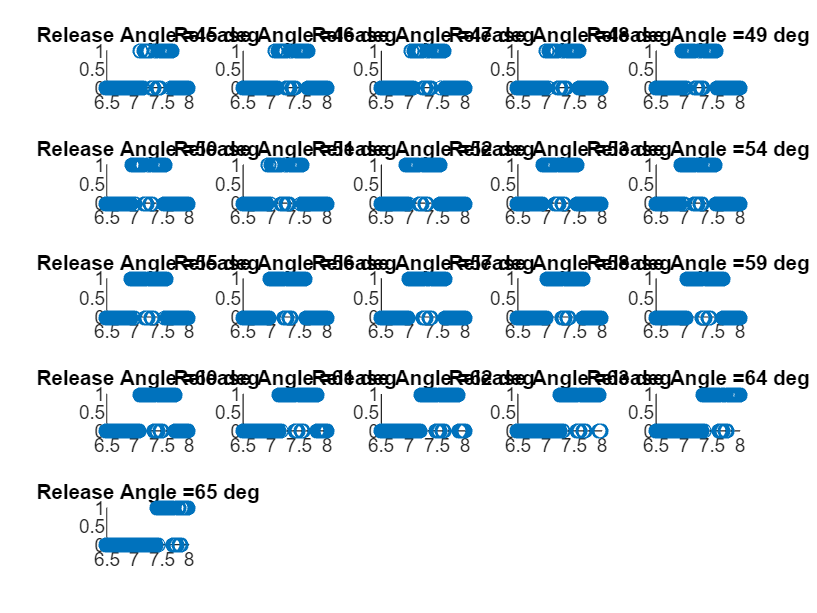

clear

load simDataPhiV0.mat
N = length(phi_vec);

figure(101); clf;
tiledlayout("flow");
for i = 1:N

    % plot results
    nexttile;
    scatter(v0_trial,makes_list{i})
    title("Release Angle ="+num2str(phi_vec(i))+" deg")

end

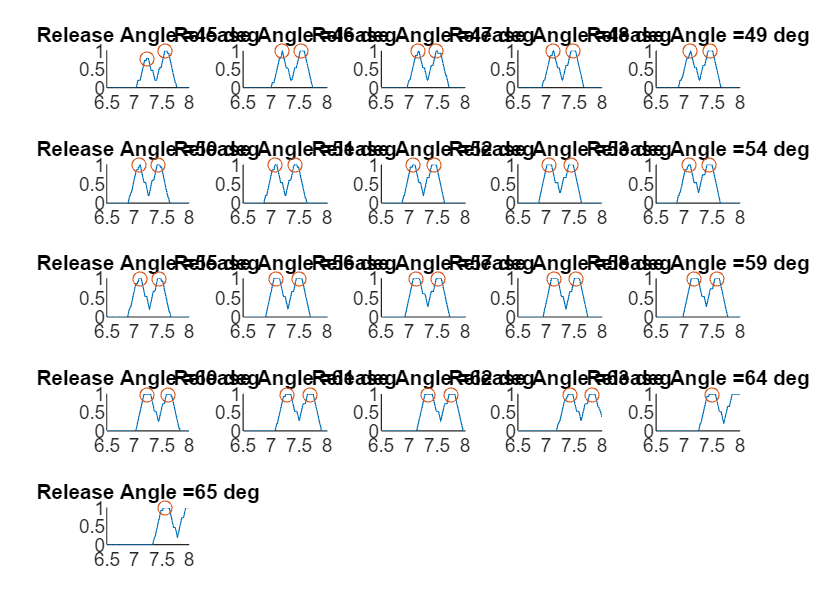


figure(201); clf;
tiledlayout("flow");
for i = 1:N

    % calculate moving average to find a local max
    makes_mean = movmean(makes_list{i},15);

    nexttile;
    hold on
    
    % plot results
    plot(v0_trial,makes_mean)
    title("Release Angle ="+num2str(phi_vec(i))+" deg")

    % find local max
    maxIndices = islocalmax(makes_mean);
    scatter(v0_trial(maxIndices),makes_mean(maxIndices))

    hold off

    % record
    v0_max = v0_trial(maxIndices);
    v0_vec(i) = v0_max(1);

end

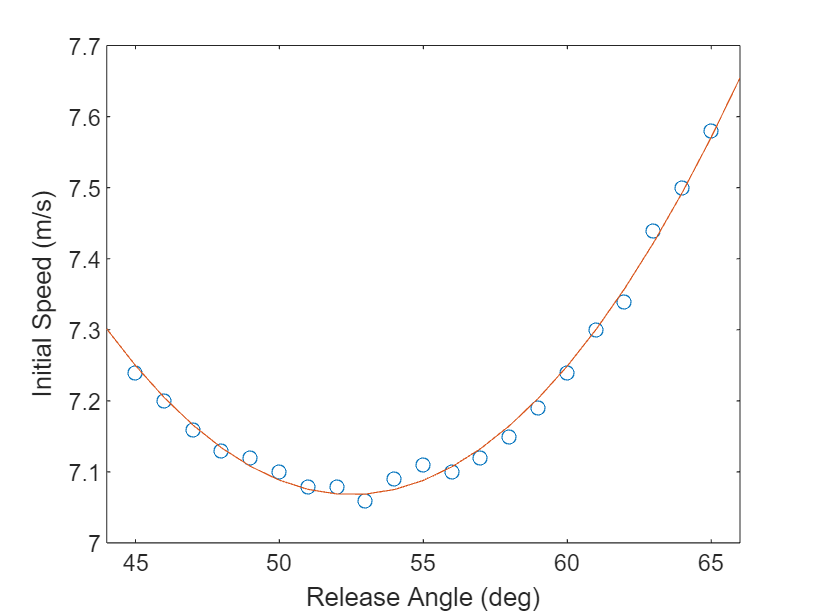


% simple curve fit to smooth out
[phi_v0_fit, gof] = fit( phi_vec', v0_vec', fittype( 'poly2' ));

figure(301); clf;
scatter(phi_vec,v0_vec)
hold on
plot(44:66,phi_v0_fit(44:66))
xlabel("Release Angle (deg)")
ylabel("Initial Speed (m/s)")
% legend("Simulation Data","Curve Fit",'Location','best')
xlim([44 66])
box on

## Save results

save("simDataPhiV0.mat",'v0_vec','phi_vec','v0_trial','makes_list','phi_v0_fit')
return